# Senzory a Měření - protokol 2 - měření střídavého napětí

Vypracoval **Vojtěch Michal** 15. března 2021, měření provedeno na dálku dne 11. 3. 2021.

Průběh všech měření byl dokumentován screenshoty vzdálené plochy s měřicími přístroji, všechny obrázky jsou k nalezení ve složce *./images. *Díky kamerám natočeným na měřicí přístroje lze ze screenshotů odečíst i měřené hodnoty.

## Triaková regulace

Triak je v principu zapojení dvou antiparalelních tyristorů se společnou řídicí elektrodou. Triak brátí průchodu elektrického proudu až do přivedení proudového pulsu na řídicí elektrodě. Tehdy se součástka otevře a propouští až do průchodu proudu nulou. Proto je vhodný na regulaci výkonu střídavého proudu, protože uřezává kousek z každé půlvlny (mezi nulou a čtvrtperiodou) a tím snižuje dobu, po kterou se odebírá výkon.

## Úkoly měření

Cílem je srovnat výsledky měření osciloskopem, trueRMS voltmetrem a levným handheld multimetrem, který RMS dopočítává jako 1.11 * SAR (rectified mean).

### 1) Vypočtěte, jakou amplitudu musíte nastavit pro dosažení stejného výkonu jako při napájení z DC

Efektivní hodnota střídavého průběhu je číselně rovna hodnotě stejnosměrného průběhu, která má na rezistivní zátěži stejné tepelné účinky. Protože pro harmonický průběh $u(t) = U_m \cdot sin(\omega t)$ platí $U_{ef} = \sqrt{\frac{1}{T} \int_0^T u^2(t) \text{d}t} = \sqrt{\frac{1}{T} \int_0^T U_m^2 \cdot sin^2(\omega t) \text{d}t} = U_m \cdot \sqrt{\frac{2}{T} \int_0^T 1-\underbrace{cos(2\omega t)}_{\text{=0 přes periodu}} \text{d}t} = U_m \cdot \sqrt{\frac{2}{T} \cdot T} = \sqrt{2} U_m$, je musíme AC nastavit amplitudu 7.07 V pro dažení stejného výkonu jako 5V DC.

### 2) Výkon zátěže, napájené 5V ef./50 Hz, je regulován obvodem emulujícím triakové spínání

Pro fázový posun 0° je triak otevřen pro celou půlvlnu, napájení je tedy harmonické. Fázový posun $\varphi = 90°$ znamená otevření jen pro polovinu každé půlvlny. Levný handheld multimetr měří jen střední aritmetickou hodnotu, násobí ji konstantou a tváří se, že to je RMS; alespoň se to dá použít pro měření SAR. TrueRMS multimetr měří jen RMS napětí, nelze z něj odečíst SAR. Osciloskop má pokročilejší matematické funkce, lze v něm nechat vypočítat hodnotu RMS i SAR.

rows = {'fáze = 0°'; 'fáze = 45°'; 'fáze = 90°'};
%Naměřená napětí ve voltech
RMS_cheapDMM = [4.910; 4.230; 2.576];
RMS_trueRMS = [5.008; 4.775; 3.5460];
RMS_oscilloscope = [4.9919; 4.7784; 3.5464];

disp('Tebulka efektivních hodnot [V]')

Tebulka efektivních hodnot [V]


table(RMS_cheapDMM, RMS_trueRMS, RMS_oscilloscope, 'RowNames', rows)

ans = 3×3 table
                  RMS_cheapDMM    RMS_trueRMS    RMS_oscilloscope
                  ____________    ___________    ________________
    fáze = 0°         4.91           5.008            4.9919     
    fáze = 45°        4.23           4.775            4.7784     
    fáze = 90°       2.576           3.546            3.5464     


SAR_cheapDMM = RMS_cheapDMM / 1.11; % Vydělením form factorem získáme SAR napětí na vstupu
SAR_trueRMS = ['N/A'; 'N/A'; 'N/A']; % Přístroj SAR neměří
SAR_oscilloscope = [4.4810; 3.8664; 2.2858]; % Počítáno jako avg(abs(u))
disp('Tabulka středních aritmetických hodnot [V]')

Tabulka středních aritmetických hodnot [V]


table(SAR_cheapDMM, SAR_trueRMS, SAR_oscilloscope, 'RowNames', rows)

ans = 3×3 table
                  SAR_cheapDMM    SAR_trueRMS    SAR_oscilloscope
                  ____________    ___________    ________________
    fáze = 0°        4.4234           N/A              4.481     
    fáze = 45°       3.8108           N/A             3.8664     
    fáze = 90°       2.3207           N/A             2.2858     

### 3) Který z multimetrů měří RMS správně

Stejné hodnoty dává měření trueRMS multimetrem i osciloskopem. Druhý multimetr není shcopen přesně měřit průběhy deformované triakovou regulací. Jak ukazuje následující tabulka, relativní chyba roste prudce spolu s mírou deformace signálu.

relErr = (RMS_trueRMS - RMS_cheapDMM) ./ RMS_trueRMS * 100;
disp('Relativní chyba výpočtu pomocí SAR vůči trueRMS měření [%]')

Relativní chyba výpočtu pomocí SAR vůči trueRMS měření [%]


table(relErr, 'RowNames', rows)

ans = 3×1 table
                  relErr
                  ______
    fáze = 0°     1.9569
    fáze = 45°    11.414
    fáze = 90°    27.355

### 4) Určete střední aritmetickou hodnotu průběhu (SAR)

Viz tabulka v úloze 2. Určení SAR umožňuje levnější multimetr, protože známe jeho princip funkce: měří SAR a násobí ji konstantním form factorem 1.11. Vydelíme-li jím zobrazenou hodnotu, získáme skutečnou hodnotu SAR.

### 5) Pro úhel $\varphi = 90°$určete ručně SAR a RMS

### 6) Změřte frekvenční závislost obou multimetrů

K dispozici je frekvenční generátor; pro dosažení $U_{ef} = 0.7$V je potřeba nastavit napětí $U_{pp} = U_{ef} * \sqrt{2} * 2 = 1.98$V špička-špička. Následně procházením spektra frekvencí a odečítáním hodnot zobrazovaných na měřicích přístrojích čekáme, kdy začne multimetr ztrácet přenost. Důvodů může být více, například narazíme na zlomovou frekvenci antialiasingových filtrů před ADC, které začnou zeslabovat vyšší generované frekvence.

rows = {'f = 10Hz'; 'f = 100Hz';'f = 1kHz';'f = 5kHz';'f = 10kHz';'f = 20kHz';'f = 50kHz';'f = 100kHz'; 'f = 200kHz';'f = 500kHz';'f = 1MHz'};
frequencies = [10 100 1000 5000 10^4 2 * 10^4 5*10^4 10^5 2*10^5 5*10^5 10^6];

cheapDMM = [0.697; 0.691; 0.679;0.525; 0.342; 0.164;0.011; 0.001; 0.000; 0.000; 0.000];
trueRMS = [0.6924;0.6996; 0.6995;0.6978;0.6965; 0.6947;0.6929;0.6880; 0.6641; 0.2595; 0.0845];
oscilloscope = [0.6856;0.6959;0.6966;0.6951;0.6937;0.6926;0.6914;0.6904; 0.6859; 0.6599; 0.5932];

disp('Měřená hodnota RMS [V] při různých frekvencích')

Měřená hodnota RMS [V] při různých frekvencích


table(cheapDMM, trueRMS, oscilloscope, 'RowNames', rows)

ans = 11×3 table
                  cheapDMM    trueRMS    oscilloscope
                  ________    _______    ____________
    f = 10Hz       0.697      0.6924        0.6856   
    f = 100Hz      0.691      0.6996        0.6959   
    f = 1kHz       0.679      0.6995        0.6966   
    f = 5kHz       0.525      0.6978        0.6951   
    f = 10kHz      0.342      0.6965        0.6937   
    f = 20kHz      0.164      0.6947        0.6926   
    f = 50kHz      0.011      0.6929        0.6914   
    f = 100kHz     0.001       0.688        0.6904   
    f = 200kHz         0      0.6641        0.6859   
    f = 500kHz         0      0.2595        0.6599   
    f = 1MHz           0      0.0845        0.

Experiment potvrzuje, že všechny tři měřicí zařízení jsou frekvenčně závislá. Při měření hodnoty RMS osciloskopem nastala u frekvencí 10, 100 a 1000 Hz hrubá lidská chyba.  Osciloskop a multimetr mají odlišené priority měření: osciloskop má poměrně málo bitů v AD převodníku, cílí na rychlost a přesnost získává průměrováním. Naopak specializovaný multimetr má přesnější AD převodník pracující na nižší vzorkovací frekvenci. Kvůli relativně nižšímu rozlišení je osciloskop náchylnější na nesprávné nastavení vertikálního měřítka (vertikálně připadá na celou obrazovku jen například $2^8$ dílků, proto nastavíme-li měřítko tak, že se signál nalézá jen v jednom z osmi vertikálních dílků, poté na signál samotný připadá pouhých $2^5$ dílků, což vede na velkou chybu měření. Není možné vyloučit, že se tato vlastnost projevila i u dalších frekvencí, proto nejsou data pro osciloskop směrodatná; lze na nich sledovat jen všeobecný trend (výpočet RMS osciloskopem je - celkem očekávatelně - obecně málo frekvenčně závislý, ovšem na frekvenci 1MHz začne být též utlumován).

### 7) Určete šířku pásma obou multimetrů

Změřená data převedeme na tvar podobný Bodeho asymptotické frekvenční charakteristice. Horizontální osu frekvencí je vhodné kvůli rozsahu 5 řádů vykreslovat logaritmicky. Data na vertikální ose normujeme na rozsah [0, 1] vydělením očekávanou hodnotou (na vstup měřicích přístrojů je přivedena efektivní hodnota 0.7V) a dále logaritmováním převedeme na decibely. Šířka pásma bude frekvence, na které přístroj bude měřit o 3 dB méně, než by měl.

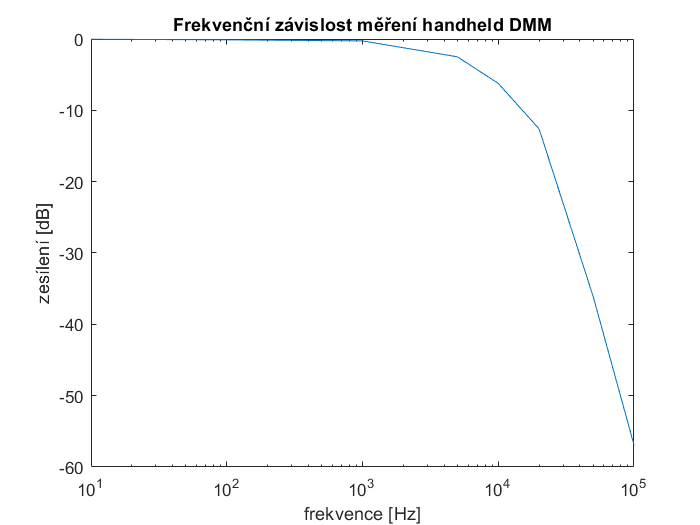

semilogx(frequencies, 20*log10(cheapDMM / 0.7));
xlabel('frekvence [Hz]');
ylabel('zesílení [dB]');
title('Frekvenční závislost měření handheld DMM');

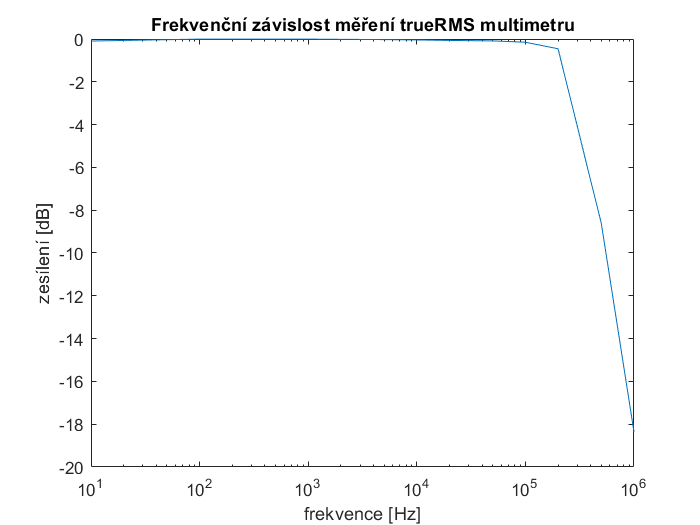

figure;
semilogx(frequencies, 20*log10(trueRMS / 0.7));
xlabel('frekvence [Hz]');
ylabel('zesílení [dB]');
title('Frekvenční závislost měření trueRMS multimetru');

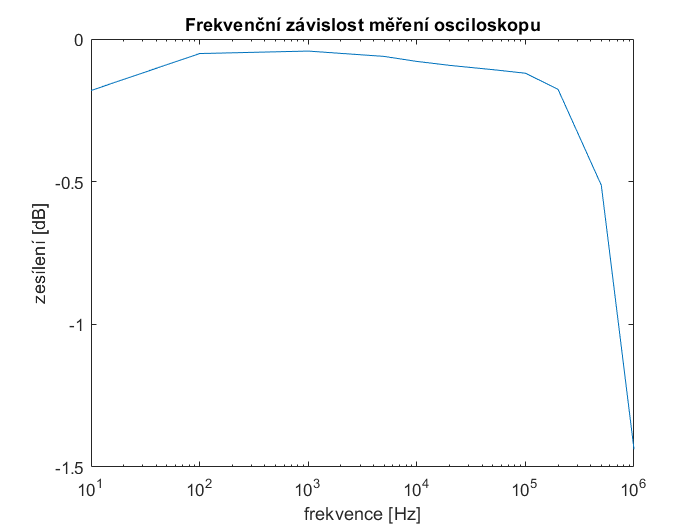

figure;
semilogx(frequencies, 20*log10(oscilloscope / 0.7));
xlabel('frekvence [Hz]');
ylabel('zesílení [dB]');
title('Frekvenční závislost měření osciloskopu');

Z vykreslených závislostí lze odhadnout čířku pásma. TrueRMS multimetr má takřka perfektní převodovou charakteristiku. Pro nízké frekvence se drží zesílení 0dB, na 200kHz má zesílení -0.4dB, na 500kHz zesílení -8.6dB. Šířka pásma tak bude cca 300kHz.

Handheld má - poměrně očkávaně - nejhorší výsledek. Zesílení -2.5dB na 5kHz, -6.2dB na 10kHz. Šířka pásma se dá očekávat někde kolem 6kHz, což je padesátkrát horší jak trueRMS multimetr.

I kdybychom se (přes dříve zmíněné nedostatky) pokusili odhadnout šířku pásma osciloskopu, neuspěli bychom. Na frekvenci $f = 10^6$Hz poklesnul osciloskop o 1.4dB, takže ještě vůbec nedosáhl svojí zlomové frekvence. Ta může být třeba na 3MHz, možná 5MHz. Každopádně výrazně dál než oba multimetry. Příčinou je, že osciloskop je na vzrokování vysokými frekvencemi stavěn a to včetně nastavení antialiasingových filtrů atp.

### 8) Pomocí funkce FFT v osciloskopu studujte spektra základních funkcí

Dostupný byl funkční generátor s harmonickým průběhem, obdélníkem a pilou. Vše studováno na 50Hz, na což musela být nastavena FFT uvnitř osciloskopu: span = 1kHz, aby bylo vidět prvních 20 harmonických. toto nastavení nabízí rozlišení Fourierky 477 mHz, takže bylo možné velice ostře odlišit peaky na přítomných harmonických.

Následující obrázek je screenshot z osciloskopu s obdélníkovým vstupním signálem. Obdélníkový průběh obsahuje pouze liché harmonické (tedy 1., 3., 5....) s amplitudami nepřímo úměrnými indexu harmonické. Oba fakty potvrzuje výsledek FFT z osciloskopu a měření pomocí kurzorů: mezi dvěma po sobě jdoucími peaky je rozestup 100Hz. Amplitudy první a třetí harmonické jsou cca. 450mV a 150mV, což souhlasí s očekávanou nepřímou závislostí na indexu harmonické.

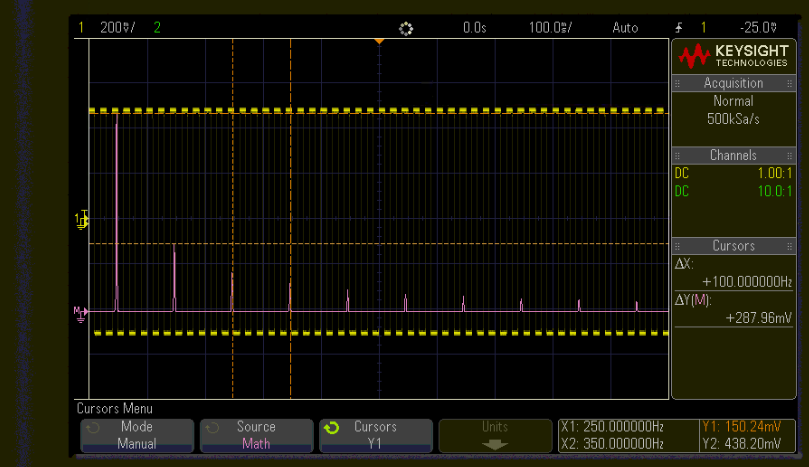

Trojúhelníkový průběh rovněž obsahuje jen liché periodické, jejich amplituda je nepřímo úměrná čtverci pořadového čísla harmonické. Z tohoto důvodu jsou harmonické velmi rychle velmi zatlumeny a nejsou pozorovatelné v lineárním měřítku. Logaritmické měřítko ukazuje, že význam mají harmonické první, třetí, ... až asi třináctá, další jsou již beznadějně ztraceny v šumu. Již třetí harmonická je oproti první zatlumená skoro o 20 dB, jedenáctá potom o víc jak 40 dB.